This code is a Finite Element Method (FEM) for solving the Poisson Equation in one dimension for a linear $f$. It is derived from the information from this [tutorial](https://www.youtube.com/watch?v=igEMh5uTQk8&t=2050s). In particular, this code solves $\frac{\partial^2V}{\partial x^2}=f(x)$, where $f(x)$ is nonconstant (though is continous and bounded on its domain), and with boundary condition on $V(0) $ and $V(d)$. It is solved over the domain $[0,d]$.

This code is initialized to solve for when $f(x)$ is a linear polynomial of the form $f(x)=mx+b$ and provides an analytical solution when this is the case, however, it can also find numerical solutions for nonlinear $f(x)$ (though it will not provide an analytical solution).

Numerical integration of $f(x)$ is done using Gaussian Quadrature with $n=3$, yielding 5 degrees of precision.

## Intitializations

clear
close all

N = 20; %number of elements in the numerical solution mesh
d = 12e-4; %we are sovling over the domain [0,d]
m = 1e10; 
b = 0.1;
f = @(x) m*x+b; %d2V/dx2 = f(x)
Vl = -0.5; %left boundary condition V(0)
Vr = -0.6; %right boundary condition V(d)


## The Analytical Solution

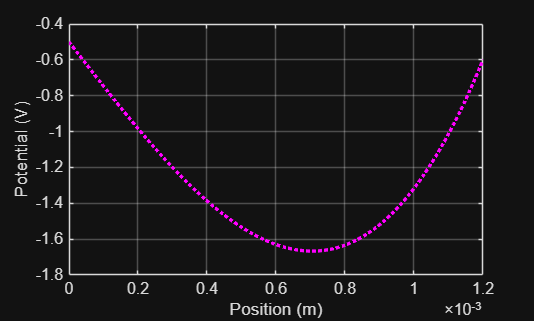

xa = linspace(0, d, 100); %defining our mesh domain for the analytical solution
Va = (m/6)*xa.^3 + (b/2)*xa.^2 + (Vr - Vl - (b/2)*d^2 - (m/6)*d^3)*xa/d + Vl; %the analytical solution

%plotting the analytical solution
plot(xa, Va, ":m", 'LineWidth',2)
xlabel('Position (m)')
ylabel('Potential (V)')
grid on
hold on

## Numerical Solution with FEM

This code represents the system as the linear system of equations $M \times V = RHS + RHS_b$, where $V$ is the matrix containing the weights of the shape function,

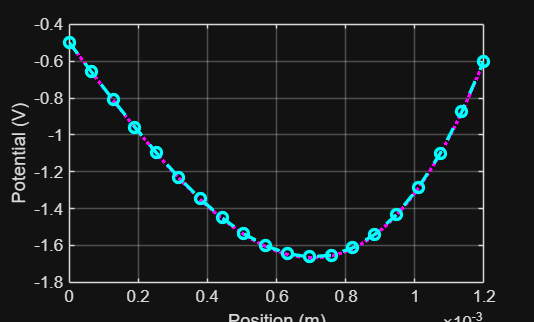

x = linspace(0,d,N); %defining our mesh domain
h(1:N-1) = x(2:N) - x(1:N-1); %defining element lengths

M = zeros(N-2, N-2); %initializing the M matrix

%defining the M matrix
M(1,1) = -1/h(1) - 1/h(2);
for i = 2:N-2
    M(i,i) = -1/h(i) - 1/h(i+1);
    M(i,i-1) = 1/h(i);
    M(i-1,i) = 1/h(i);
end

RHS = zeros(N-2,1); %initializing the RHS matrix

%defining RHS
for i = 1:N-2
    %defining fz for the element of interest and over ζ [-1,1]
    fz = @(z,i) f(x(i) + 0.5*h(i)*(z+1));
    %defining the function used for gaussian quadrature calculations (to clean up the code)
    g = @(z,i) fz(z,i)*(1-z);
    RHS(i) = 0.25*(h(i)*((5/9)*g(sqrt(3)/5,i)+(5/9)*g(-sqrt(3)/5,i)+(8/9)*g(0,i)) + h(i+1)*((5/9)*g(sqrt(3)/5,i+1)+(5/9)*g(-sqrt(3)/5,i+1)+(8/9)*g(0,i+1))); %calculating with gaussian quadrature using n=3
end

RHSB = zeros(N-2,1); %initializing the RHSB matrix which represents the boundary conditions

%defining RHSB
RHSB(1) = -Vl/h(1);
RHSB(end) = -Vr/h(end);

VNc = M\(RHS+RHSB); %numerical solution in the central part of hte matrix

VN = zeros(N,1);
VN(1) = Vl; %enforcing left BC
VN(end) = Vr; %enforcing right BC

for i = 1:N-2
    VN(i+1) = VNc(i);
end

%plotting the numerical solution against the analytical one
plot(x, VN, "c--o", 'LineWidth',2)